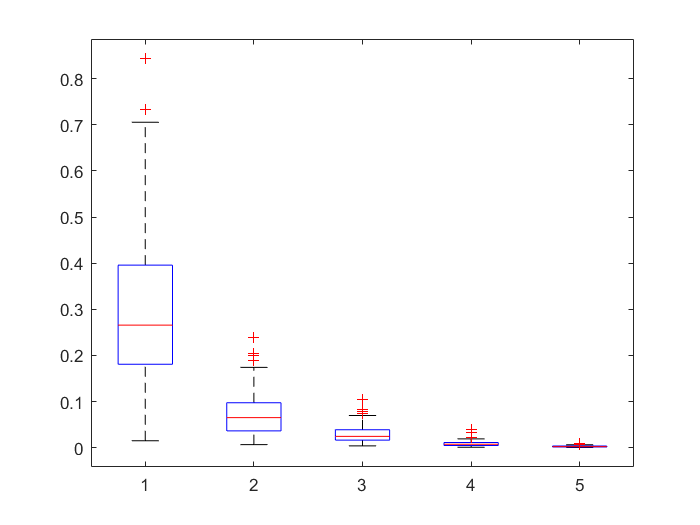

N_arr=[10, 100, 1000, 10000, 100000];
mu=[1;2]; % The mean vector
cov=[1.6250, -1.9486; -1.9486, 3.8750]; % The covariance matrix
[Q,eigval]=eig(cov);
transform=Q*(sqrt(eigval));

rng(0);
meanEstimate=zeros(100, 5);
covSampleError=zeros(100, 5);

for n=1:5
    N=N_arr(n);
    answ=zeros(2, N);
    final1=zeros(2, N);

    for k=1:100
        % Generating 
        for i = 1:2
            for j = 1:N
                answ(i, j)=randn();
            end
        end

        %transforming
        final1=transform*answ+mu;
        mle=sum(final1, 2)/N;
        meanEstimate(k, n)=(sqrt((mle(1,1)-1)^2+(mle(2,1)-2)^2))/sqrt(5);
        covars = final1-mle;
        covmat = covars*covars'/N;
        covSampleError(k, n) = norm(covmat - cov, 'fro')/norm(cov, 'fro');
    end
end
boxplot(meanEstimate, log10(N_arr));

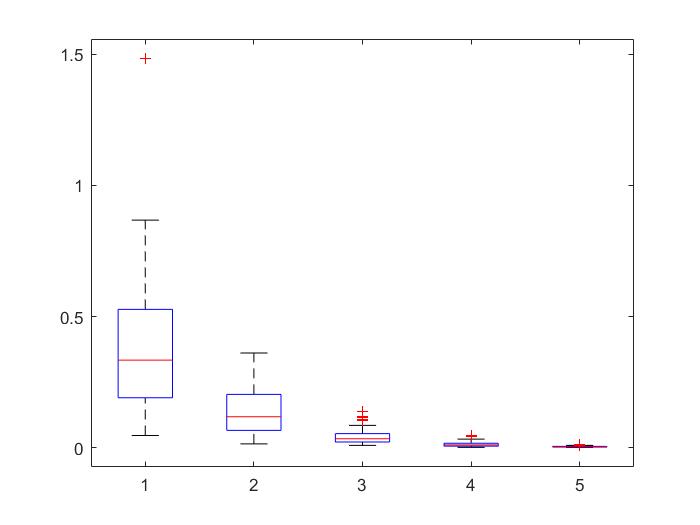

boxplot(covSampleError, log10(N_arr));